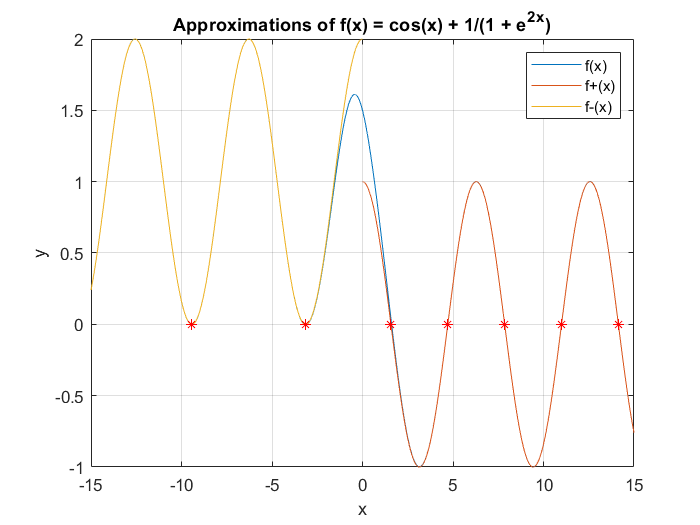

x = linspace(-15, 15, 10000);
f = cos(x) + 1./(1 + exp(2*x));
plot(x, f)
hold on
ylim([-1,2])
grid on
x2 = linspace(0, 15, 10000);
x3 = linspace(-15, 0, 10000);
fpos = cos(x2);
fneg = cos(x3) + 1;
plot(x2, fpos)
hold on
plot(x3, fneg)
hold on
for n = [1:5]
    plot(pi.*(n - 1/2), 0, 'r*')
end
for n = [-2:-1]
    plot(2*pi.*n + pi, 0, 'r*')
end
legend('f(x)','f+(x)','f-(x)')
xlabel('x'), ylabel('y')
title 'Approximations of f(x) = cos(x) + 1/(1 + e^2^x)'